# Taller 8 - Reto

    clc, clear all, close all;

### **Modelado del Circuito RLC**

### La función de transferencia de un circuito RLC en serie, tomando el voltaje en el condensador como salida es: 

### 
$$G\left(s\right)=\;\frac{V_o (s)}{V_i (s)}=\frac{\frac{1}{LC}}{s^2 +\frac{R}{L}s+\frac{1}{LC}}$$


    % Parámetros del circuito
    R = 22;     %[Ohm]
    L = 500e-6; %[H]
    C = 220e-6; %[F]
    
    % Función de transferencia RLC
    num = [1/(L*C)];
    den = [1 R/L 1/(L*C)];
    Gs = tf(num, den)

Gs =
 
          9.091e06
  ------------------------
  s^2 + 44000 s + 9.091e06
 
Continuous-time transfer function.
Model Properties


    
    % Polos y ceros
    polos = pole(Gs)

polos = 1.0e+04 *

   -4.3792
   -0.0208


Graficas de la respuesta y lgr

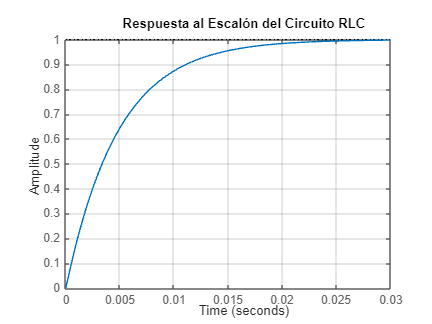

    step(Gs)
    title('Respuesta al Escalón del Circuito RLC');
    grid on;

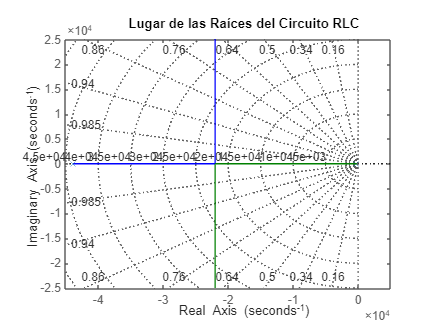

    
    rlocus(Gs);
    title('Lugar de las Raíces del Circuito RLC');
    grid on;

Diseño del Compensador; $M_p =25%\;\textrm{y}\;t_{ss} =50ms$

    Mp = 0.25;   
    tss = 0.050; %[s]
    
    zeta = log(1/Mp)/sqrt(pi^2 + (log(1/Mp))^2)

zeta = 0.4037

    wn = 4/(tss * zeta)

wn = 198.1607

    
    % Polos objetivo (raíces deseadas)
    den_deseado = [1 2*zeta*wn wn^2];
    raices_deseadas = roots(den_deseado)

raices_deseadas = 1.0e+02 *

  -0.8000 + 1.8129i
  -0.8000 - 1.8129i


#### Graficar Polos del proceso original y polos de la respuesta deseada

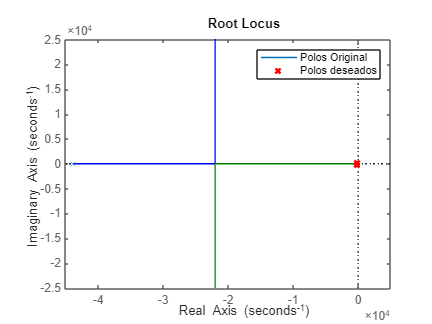

    figure
    rlocus(Gs)
    hold on;  % Superponer graficos
    plot(real(raices_deseadas), imag(raices_deseadas), 'rx', 'LineWidth', 2);
    hold off; legend("Polos Original", "Polos deseados");

Diseño del compensador en adelanto

    % Geometría para el polo del compensador    
    m = (imag(raices_deseadas(1))-0)/(real(raices_deseadas(1))-polos(1))

m = 0.0041

    theta1 = 180 + rad2deg(atan(m))

theta1 = 180.2376

    theta4 = abs(180 - theta1) % Ángulo de deficiencia

theta4 = 0.2376

    
    p_c = real(raices_deseadas(1)) - (imag(raices_deseadas(1))/tand(theta4))

p_c = -4.3792e+04

    z_c = polos(2) 

z_c = -207.5910

    
    % Formación del compensador (sin Kc)
    G1c = tf([1 -z_c], [1 -p_c])

G1c =
 
   s + 207.6
  ------------
  s + 4.379e04
 
Continuous-time transfer function.
Model Properties


    
    % Sistema compensado (sin Kc)
    G1col = series(G1c, Gs)  % Open loop

G1col =
 
            9.091e06 s + 1.887e09
  ------------------------------------------
  s^3 + 8.779e04 s^2 + 1.936e09 s + 3.981e11
 
Continuous-time transfer function.
Model Properties


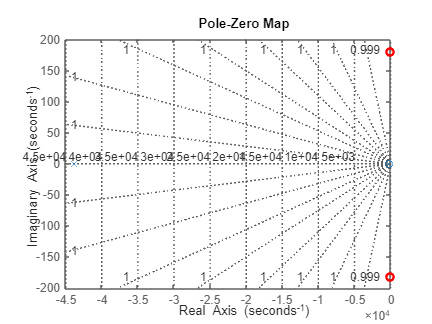

    figure()
    pzplot(G1col)
    hold on;
    plot(real(raices_deseadas), imag(raices_deseadas), 'ro', 'LineWidth', 2, 'DisplayName', 'Polos Deseados');
    grid on; hold off;

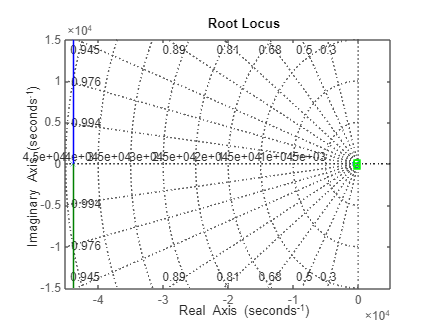

    
    figure()
    rlocus(G1col)
    hold on;  % Superponer graficos
    plot(real(raices_deseadas), imag(raices_deseadas), 'gs', 'LineWidth', 2, 'DisplayName', 'Objetivo');
    grid on;

    
    
    % Cálculo de Kc
    Hs = 1; % Retroalimentación unitaria
    Kc = 1 / abs(evalfr(G1c * Gs * Hs, raices_deseadas(1)))

Kc = 210.1888

    Gc = Kc * G1c

Gc =
 
  210.2 s + 4.363e04
  ------------------
     s + 4.379e04
 
Continuous-time transfer function.
Model Properties


Graficas

    Gccl = feedback(Gc * Gs, Hs);
    Gccl = Gccl / dcgain(Gccl) % Normalizar para alcanzar el mp solicitado

Gccl =
 
               1.911e09 s + 3.967e11
  ------------------------------------------------
  0.4991 s^3 + 4.382e04 s^2 + 1.92e09 s + 3.967e11
 
Continuous-time transfer function.
Model Properties


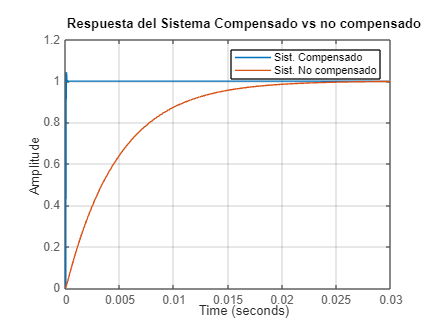

    [y, t] = step(Gccl);
    [mp, idx] = max(y);
    
    figure()
    step(Gccl)
    hold on;
    step(Gs)
    grid on; 
    title('Respuesta del Sistema Compensado vs no compensado');
    legend("Sist. Compensado", "Sist. No compensado");

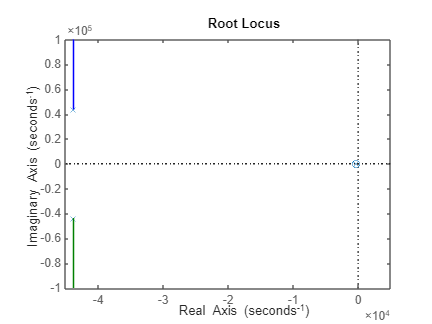

    
    figure()
    rlocus(Gccl)

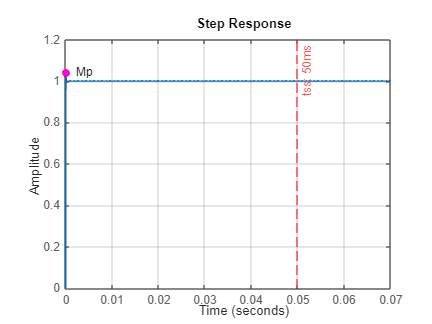

    
    figure()
    step(Gccl)
    grid on; hold on;
    xline(tss, '--r', 'tss: 50ms');
    plot(t(idx), mp, 'ro', 'MarkerFaceColor', 'm');
    text(t(idx), mp, '   Mp'); 